# Shinbrot Targeting Walkthrough

This Live Script is the principal explanatory walkthrough for the final Shinbrot Lorenz targeting implementation in this folder. It is not a replacement for the verified computational functions. Instead, it calls those functions in a documented order and displays the intermediate diagnostics, tables and figures inline.

The study has three connected parts:

1. a deterministic single-source demonstration comparing the verified Shinbrot discontinuity-aware bisection search with the deterministic grid-first hybrid extension; 2. a deterministic 60-source benchmark loaded from verified saved results generated by the current code; 3. a fixed-step RK4 Gaussian-noise investigation using the verified bisection method with accepted-section retargeting.

The hybrid method is a deterministic extension for comparison. It is not used in the noise investigation.

## Reproducible Project Setup

The script first locates the Shinbrot project folder, moves MATLAB into that folder, and adds only that folder to the path. This avoids hidden dependencies on a previous MATLAB session. The switches below prevent expensive studies from being regenerated unless explicitly requested. In normal use the Live Script loads the verified saved ensemble and noise results and then plots them inline.

clearvars;
close all;
clc;

projectPath = walkthrough_project_path();
restoredefaultpath;
rehash toolboxcache;
cd(projectPath);
addpath(projectPath);
rng(7, 'twister');

runExpensiveEnsemble = false;
runExpensiveNoiseSweep = true;
runNoiseSmokeOnly = true;
runControlBoundSweep = false;

setupTable = table(string(projectPath), runExpensiveEnsemble, ...
    runExpensiveNoiseSweep, runNoiseSmokeOnly, runControlBoundSweep, ...
    'VariableNames', {'ProjectPath', 'RunExpensiveEnsemble', ...
    'RunExpensiveNoiseSweep', 'RunNoiseSmokeOnly', ...
    'RunControlBoundSweep'});
disp(setupTable);

                                        ProjectPath                                         RunExpensiveEnsemble    RunExpensiveNoiseSweep    RunNoiseSmokeOnly    RunControlBoundSweep
    ____________________________________________________________________________________    ____________________    ______________________    _________________    ____________________

    "C:\Users\npcoz\OneDrive - Imperial College London\Project\Codes\Shinbrot targeting"           false                    true                    true                  false        



## Lorenz System

The controlled Lorenz equations used throughout the implementation are


$$\dot{x} = \sigma(y-x),$$



$$\dot{y} = x(\rho-z)-y+p_{\mathrm{control}},$$



$$\dot{z} = xy-\beta z.$$


The standard Lorenz parameters are $\sigma=10$, $\rho=28$ and $\beta=8/3$. The targeting parameter $p_{\mathrm{control}}$ is a bounded additive perturbation in the $y$-equation. It is not a state kick. During a deterministic targeting replay the selected value is held constant from the source Poincare crossing until the selected target horizon has been reached.

verifiedBisectionIdentifier = verified_bisection_identifier();

params.sigma = 10;
params.rho = 28;
params.beta = 8/3;
params.zSection = 26.921;
params.xSectionMin = 8.0;
params.crossingDirection = +1;
params.odeOptions = odeset('RelTol', 1e-9, 'AbsTol', 1e-11);
params.eventDisableTime = 1e-6;
params.maxStepOffSection = 1e-5;
params.sectionTolerance = 1e-9;
params.maxTimeToNextValidSection = 100;
params.maxRejectedCrossings = 100;

lorenzParameterTable = table(params.sigma, params.rho, params.beta, ...
    'VariableNames', {'sigma', 'rho', 'beta'});
disp(lorenzParameterTable);

    sigma    rho     beta 
    _____    ___    ______

     10      28     2.6667



## Poincare Section

The implementation converts the continuous Lorenz flow into a scalar return-map problem by recording accepted crossings of the half-plane


$$z = 26.921,\qquad x > 8.$$


The event function detects the directed crossing of the plane $z=26.921$. The half-plane condition $x>8$ is then enforced by `next_valid_section_crossing`, which rejects plane crossings on the other side and continues integration. The accepted crossing direction is positive and the section tolerance is `params.sectionTolerance`.

sectionTable = table(params.zSection, params.xSectionMin, ...
    params.crossingDirection, params.sectionTolerance, ...
    params.eventDisableTime, params.maxStepOffSection, ...
    'VariableNames', {'zSection', 'xSectionMin', ...
    'CrossingDirection', 'SectionTolerance', 'EventDisableTime', ...
    'MaxStepOffSection'});
disp(sectionTable);

    zSection    xSectionMin    CrossingDirection    SectionTolerance    EventDisableTime    MaxStepOffSection
    ________    ___________    _________________    ________________    ________________    _________________

     26.921          8                 1                 1e-09               1e-06                1e-05      



## Target Periodic Orbit

The target is represented on the accepted Poincare section by the fixed scalar coordinate $X_t=13.729$ and the associated three-dimensional section state. Success is not exact equality with the target point; instead, a replay is successful when the accepted crossing satisfies


$$|X_n-X_t|\leq 0.008.$$


This neighbourhood definition is necessary because the targeting computation is numerical and because the target point is a representative fixed point of the return-map dynamics.

target.x = 13.729;
target.state = [13.729; 19.585; params.zSection];
target.tolerance = 0.008;

targetTable = table(target.x, target.state(1), target.state(2), ...
    target.state(3), target.tolerance, ...
    'VariableNames', {'TargetX', 'TargetStateX', 'TargetStateY', ...
    'TargetStateZ', 'TargetTolerance'});
disp(targetTable);

    TargetX    TargetStateX    TargetStateY    TargetStateZ    TargetTolerance
    _______    ____________    ____________    ____________    _______________

    13.729        13.729          19.585          26.921            0.008     



## Search Settings

Both deterministic methods use the same dynamical settings, target tolerance and parameter bound. The admissible parameter interval is $[-\Delta p,\Delta p]$ with $\Delta p=0.1$. The deterministic search horizon is the number of accepted Poincare crossings after the source state. The hybrid method additionally evaluates the full parameter grid before refining verified candidates.

control.deltaP = 0.1;
control.maxSearchCrossings = 12;
control.numParameterSamples = 81;
control.bisectionIterations = 24;
control.maxDiscontinuityIsolationDepth = 24;
control.maxDiscontinuityIntervals = 256;
control.searchMethod = 'hybridGridBisection';

benchmarkSettings.repetitions = 5;

controlTable = table(control.deltaP, control.maxSearchCrossings, ...
    control.numParameterSamples, control.bisectionIterations, ...
    control.maxDiscontinuityIsolationDepth, ...
    control.maxDiscontinuityIntervals, ...
    string(verifiedBisectionIdentifier), ...
    'VariableNames', {'DeltaP', 'MaxSearchCrossings', ...
    'ParameterSamples', 'BisectionIterations', ...
    'MaxDiscontinuityIsolationDepth', 'MaxDiscontinuityIntervals', ...
    'VerifiedBisectionIdentifier'});
disp(controlTable);

    DeltaP    MaxSearchCrossings    ParameterSamples    BisectionIterations    MaxDiscontinuityIsolationDepth    MaxDiscontinuityIntervals    VerifiedBisectionIdentifier
    ______    __________________    ________________    ___________________    ______________________________    _________________________    ___________________________

     0.1              12                   81                   24                           24                             256                "shinbrotPaperBisection"  



## Source-State Construction

The nominal return map is generated with `pControl = 0`. The principal source is the full three-dimensional state at the 150th accepted section crossing from the initial Lorenz state `[1;1;1]`. The scalar coordinate is used for the return-map search, but the full state is retained for every independent replay.

fprintf('Generating the uncontrolled Poincare return map...\n');

Generating the uncontrolled Poincare return map...


X0 = [1; 1; 1];
numMapCrossings = 1200;
sourceIndex = 150;
mapData = generate_return_map(X0, numMapCrossings, params, 0);
if size(mapData.states, 2) < numMapCrossings
    error('Only %d valid section crossings were generated.', ...
        size(mapData.states, 2));
end

sourceState = mapData.states(:, sourceIndex);
if abs(sourceState(1) - target.x) <= target.tolerance
    error('The configured source point lies inside the target interval.');
end
sourceX = sourceState(1);

sourceSummary = table(sourceIndex, sourceX, target.x, ...
    abs(sourceX - target.x), numMapCrossings, ...
    'VariableNames', {'SourceIndex', 'SourceX', 'TargetX', ...
    'InitialScalarSeparation', 'GeneratedMapCrossings'});
disp(sourceSummary);

    SourceIndex    SourceX    TargetX    InitialScalarSeparation    GeneratedMapCrossings
    ___________    _______    _______    _______________________    _____________________

        150        12.807     13.729             0.92231                    1200         



## Lorenz Attractor, Section and Accepted Crossings

The following figure shows the nominal trajectory used to build the return map, the accepted half-plane, the target point and the selected source point. The accepted section states are overlaid so the scalar sequence can be seen as samples of the continuous flow.

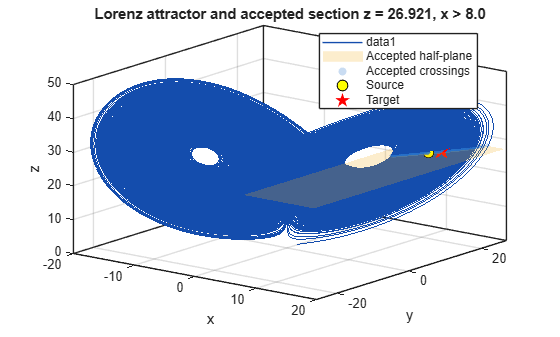

walkthrough_plot_lorenz_section(mapData, sourceState, target, params);

## Scalar Return Map

Consecutive accepted crossings define a one-dimensional return-map view: $X_{n+1}=F(X_n)$. The target fixed point is shown against the identity line. This plot is only a scalar projection of the full section state; all replay verification still reintegrates the full Lorenz equations.

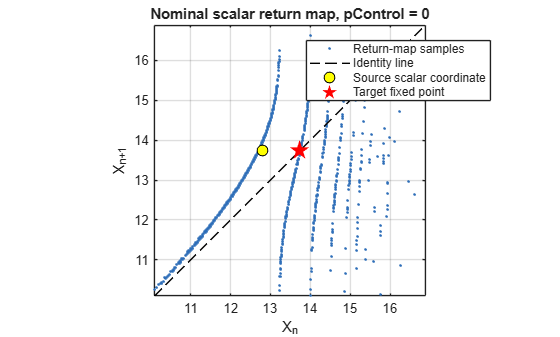

walkthrough_plot_return_map(mapData, sourceState, target);

## Uncontrolled Baseline

The uncontrolled baseline starts from the same source state and sets `pControl = 0`. It counts accepted section crossings until the target neighbourhood is reached or until the configured maximum number of crossings is exhausted. This is the natural-recurrence reference against which the controlled searches are compared.

fprintf('Running the uncontrolled recurrence baseline...\n');

Running the uncontrolled recurrence baseline...


uncontrolled = uncontrolled_hitting_time_1d( ...
    sourceState, target, params, 2000);

uncontrolledTable = table(uncontrolled.hit, uncontrolled.numCrossings, ...
    uncontrolled.physicalTime, numel(uncontrolled.xSequence), ...
    'VariableNames', {'Hit', 'AcceptedCrossingsToHit', ...
    'PhysicalTimeToHit', 'StoredScalarSequenceLength'});
disp(uncontrolledTable);

     Hit     AcceptedCrossingsToHit    PhysicalTimeToHit    StoredScalarSequenceLength
    _____    ______________________    _________________    __________________________

    true              266                   400.01                     267            



## Shinbrot Discontinuity-Aware Bisection

The verified Shinbrot search calls `search_parameter_to_target` with the dispatcher identifier `shinbrotDiscontinuityAwareBisection`. Internally, `run_shinbrot_discontinuity_aware_bisection` subdivides the full bounded interval, compares ordered left/right crossing signatures, isolates continuous target brackets, and then refines only brackets whose endpoint images remain on the same branch and contain the target.

This section does not reproduce a second bisection algorithm. It calls the verified `.m` implementation and then displays the search metadata: discontinuity counts, crossing-signature evaluations, bracket bounds, selected horizon, selected parameter and target error.

fprintf('Running the verified Shinbrot bisection search...\n');

Running the verified Shinbrot bisection search...


bisectionControl = control;
bisectionControl.searchMethod = verifiedBisectionIdentifier;
bisectionSearch = search_parameter_to_target( ...
    sourceState, target, params, bisectionControl, ...
    verifiedBisectionIdentifier);
assert_verified_bisection_search( ...
    bisectionSearch, verifiedBisectionIdentifier, ...
    'principal deterministic bisection');

bisectionReplayTimer = tic;
bisectionReplay = walkthrough_replay_parameter( ...
    sourceState, target, params, bisectionSearch);
bisectionReplay.replayTime = toc(bisectionReplayTimer);

bisectionSearchTable = walkthrough_bisection_diagnostics( ...
    bisectionSearch, bisectionReplay);
disp(bisectionSearchTable);

             Method             SearchFound    ReplayHit    SelectedP      AbsP      Horizon    SearchTargetError    ReplayTargetError    SearchTime    ReplayTime    ParameterEvaluations    CrossingPropagations    TotalBisectionIterations    CrossingSignatureEvaluations    DiscontinuitiesDetected    DiscontinuityReductions    ContinuousIntervalsExamined    ContinuousTargetBracketFound    BracketLow    BracketHigh                               SelectionMethod                            
    ________________________    ___________    _________    _________    ___

## Hybrid Grid-First/Bisection Method

The hybrid method is an addition to the original Shinbrot procedure. At each horizon it evaluates the complete parameter grid, records all direct grid hits and all adjacent sign-change brackets, then bisects each verified adjacent bracket. Candidate selection is lexicographic:

1. smallest targeting horizon; 2. smallest `abs(pControl)`; 3. smallest final target residual.

The search is still verified by direct integration from the original source state. A sign change alone is not treated as a hit.

fprintf('Running the deterministic grid-first hybrid search...\n');

Running the deterministic grid-first hybrid search...


hybridControl = control;
hybridControl.searchMethod = 'hybridGridBisection';
hybridSearch = search_parameter_to_target( ...
    sourceState, target, params, hybridControl, 'hybridGridBisection');

hybridReplayTimer = tic;
hybridReplay = walkthrough_replay_parameter( ...
    sourceState, target, params, hybridSearch);
hybridReplay.replayTime = toc(hybridReplayTimer);

hybridSearchTable = walkthrough_hybrid_diagnostics(hybridSearch, hybridReplay);
disp(hybridSearchTable);

           Method            SearchFound    ReplayHit    SelectedP      AbsP      Horizon    SearchTargetError    ReplayTargetError    SearchTime    ReplayTime    ParameterEvaluations    CrossingPropagations    GridEvaluations    FinalBracketBisectionIterations    TotalBisectionIterations    BracketLow    BracketHigh                       SelectionMethod                   
    _____________________    ___________    _________    _________    ________    _______    _________________    _________________    __________    ________


hybridFeatureTable = walkthrough_hybrid_feature_table( ...
    hybridSearch, target);
disp(hybridFeatureTable);

    Horizon    DirectGridHits    AdjacentBrackets    VerifiedCandidates    MinimumGridDistance    TargetTolerance
    _______    ______________    ________________    __________________    ___________________    _______________

       1             0                   0                   0                   0.22626               0.008     
       2             0                   1                   0                    1.2759               0.008     
       3             0                  14                   7                  0.010497               0.008     
       4             0                   0                   0                       NaN               0.008     
       5             0                   0                   0                       NaN               0.008   

## Principal Deterministic Comparison

Both procedures are now compared from the same source. The reference values below are verification references from the current implementation, not values used to select the controls. The table is generated from the executed searches and independent replays.

principalComparison = walkthrough_principal_comparison_table( ...
    bisectionSearch, bisectionReplay, hybridSearch, hybridReplay);
disp(principalComparison);

           Method           Success    ReplayHit    SelectedControl    AbsControl    Horizon    FinalTargetError    ReplayTargetError    SearchTime    ReplayTime    TotalComputationalTime                               SelectionMethod                            
    ____________________    _______    _________    _______________    __________    _______    ________________    _________________    __________    __________    ______________________    ______________________________________________________________________

    "Shinbrot bisection"     true        true          0.086546    


% The checks below assert the properties a valid result must have, not the
% particular numbers a given implementation happens to return.  Pinning
% literal values here made the walkthrough a record of one implementation
% rather than a verification of the method, and it is what allowed this
% file and Table 2 of the report to drift apart.  The returned values are
% displayed in principalComparison above rather than asserted.

walkthrough_assert_valid_result(bisectionSearch, bisectionReplay, ...
    target, control, 'Shinbrot bisection');

Shinbrot bisection: verified. p = 0.08654567227, n = 3, replay error = 4.06482e-09, search-replay divergence = 1.21e-12


walkthrough_assert_valid_result(hybridSearch, hybridReplay, ...
    target, control, 'Grid-first hybrid');

Grid-first hybrid: verified. p = 0.019375, n = 3, replay error = 0.000563047, search-replay divergence = 0
  Note: the divergence is exactly zero, so the replay repeated the search's
  own propagation rather than recomputing it independently. The search and the
  replay reach the section through the same function, so agreement is guaranteed
  and is not evidence that the returned perturbation is correct. The perturbation
  is not thereby wrong; this particular check simply carries no weight for it.



if bisectionSearch.horizon ~= hybridSearch.horizon
    fprintf(['Note: the methods selected different horizons (%d and %d). ', ...
        'Perturbation magnitudes are not directly comparable at ', ...
        'different horizons.\n'], bisectionSearch.horizon, hybridSearch.horizon);
end

## Controlled Replay and Verification

The selected controls are replayed independently of the search calculations. A method is reported as successful here only if the reintegrated controlled trajectory enters the target neighbourhood at the selected accepted crossing.

replayVerification = table( ...
    ["Shinbrot bisection"; "Grid-first hybrid"], ...
    [bisectionReplay.hit; hybridReplay.hit], ...
    [bisectionReplay.numCrossings; hybridReplay.numCrossings], ...
    [bisectionReplay.targetError; hybridReplay.targetError], ...
    [bisectionReplay.replayTime; hybridReplay.replayTime], ...
    'VariableNames', {'Method', 'ReplayHit', 'ReplayCrossings', ...
    'ReplayTargetError', 'ReplayTime'});
disp(replayVerification);

           Method           ReplayHit    ReplayCrossings    ReplayTargetError    ReplayTime
    ____________________    _________    _______________    _________________    __________

    "Shinbrot bisection"      true              3              4.0648e-09          0.07395 
    "Grid-first hybrid"       true              3              0.00056305         0.056578 



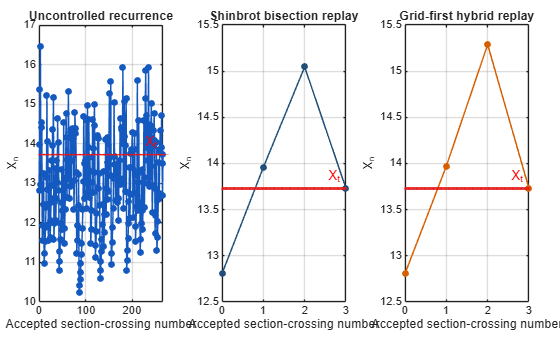


walkthrough_plot_section_sequences( ...
    uncontrolled, bisectionReplay, hybridReplay, target);

walkthrough_plot_controlled_phase_space( ...
    mapData, uncontrolled, bisectionReplay, hybridReplay, ...
    sourceState, target, params);

## Search Behaviour Figures

The bisection method is represented by its final bracket and counters, while the hybrid method has a complete residual curve at the selected horizon. The figure below displays both forms of search evidence without replacing either algorithm.

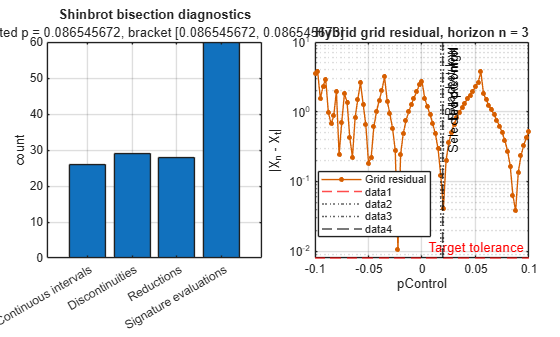

walkthrough_plot_search_behaviour( ...
    bisectionSearch, hybridSearch, target, control);

## RMS Scale and Timing Benchmark

The time-weighted RMS of the nominal vector field gives a scale for the perturbation in the Lorenz equations. The five-repetition timing benchmark times the two deterministic search-and-replay workflows from the already selected source state.

fprintf('Computing the post-transient time-weighted RHS RMS...\n');

Computing the post-transient time-weighted RHS RMS...


rhsRms = walkthrough_compute_rhs_rms(mapData, params, control, 100);
disp(struct2table(rhsRms));

    rmsFx     rmsFy     rmsFz    transientCrossingIndex    transientTime    averagingDuration    maxParameterEffect    parameterToRmsFyRatio    paperApproximateRmsFy    rmsFyDifferenceFromPaperApproximation
    ______    ______    _____    ______________________    _____________    _________________    __________________    _____________________    _____________________    _____________________________________

    42.731    65.409    78.84             100                 161.28             1670.5                 0.1                  0.0015288                   100                            -34.591               




fprintf('Benchmarking the deterministic bisection and hybrid methods...\n');

Benchmarking the deterministic bisection and hybrid methods...


searchBenchmark = benchmark_shinbrot_search_methods( ...
    sourceState, target, params, control, benchmarkSettings);
disp(searchBenchmark.comparisonTable);

              Method              HitFound    SelectedP    Horizon    FinalError    ParameterEvaluations    CrossingPropagations    FinalBracketBisectionIterations    TotalBisectionIterations    GridEvaluations    MedianSearchTime    ControlledReplayCrossings    ReplayHit    MedianReplayTime    MedianSearchAndReplayTime                                SelectionMethod                                 FailureCode    FailureReason
    __________________________    ________    _________    _______    __________    ____________________    ____________________    _____

## Sixty-Source Ensemble Benchmark

The deterministic ensemble uses 60 source states chosen from accepted return-map indices 100:300, with scalar separation `abs(X_s-X_t) >= 1.5`. Each selected source is tested once with the Shinbrot bisection method and once with the hybrid method. The saved result is accepted only when its metadata match the current target, control settings, method names, source count and table schema.

Regeneration is deliberately controlled by `runExpensiveEnsemble` because the existing verified `.mat` and `.csv` files are the current numerical authority for the ensemble section.

sourceEnsembleSettings.candidateIndices = 100:300;
sourceEnsembleSettings.numSources = 60;
sourceEnsembleSettings.sourceSeparation = 1.5;
sourceEnsembleSettings.outputMatFile = 'shinbrot_source_ensemble.mat';
sourceEnsembleSettings.methodResultsCsv = ...
    'shinbrot_source_ensemble_method_results.csv';
sourceEnsembleSettings.pairedResultsCsv = ...
    'shinbrot_source_ensemble_paired_results.csv';

if runExpensiveEnsemble
    sourceEnsemble = benchmark_shinbrot_source_ensemble( ...
        mapData, target, params, control, sourceEnsembleSettings);
else
    savedEnsemble = load(sourceEnsembleSettings.outputMatFile);
    if ~walkthrough_is_valid_source_ensemble(savedEnsemble, target, control)
        error(['Saved 60-source ensemble results are missing or stale. ', ...
            'Set runExpensiveEnsemble = true to regenerate them.']);
    end
    sourceEnsemble = savedEnsemble;
end

disp(sourceEnsemble.methodSummary);

              Method              NumberSources    NumberReplayHits    SuccessRate    MeanHorizon    MedianHorizon    MeanAbsoluteP    MedianAbsoluteP    MeanReplayTargetError    MedianReplayTargetError    MaximumReplayTargetError    MeanSearchTime    MedianSearchTime
    __________________________    _____________    ________________    ___________    ___________    _____________    _____________    _______________    _____________________    _______________________    ________________________    ______________    ________________

    {'shinbrotPaper

disp(sourceEnsemble.summary);

    NumberSourcesTested    NumberShinbrotReplayHits    NumberHybridReplayHits    ShinbrotSuccessRate    HybridSuccessRate    NumberBothReplayHit    NumberSameSuccessfulHorizon    NumberDifferentSuccessfulHorizons    MatchedHybridSmaller    MatchedShinbrotSmaller    MatchedTies                                                                                          HybridSmallerSourceIndices                                                                                                  ShinbrotSmallerSourceIndices            TieSourceIndices    MeanShinbrotAbsoluteP    MedianShinbrotAbsoluteP    MeanHybridAbsoluteP    MedianHybridAbsoluteP    MeanAbsolutePDifference   


ensembleExcerpt = sourceEnsemble.pairedResultsTable(1:min(12, ...
    height(sourceEnsemble.pairedResultsTable)), :);
disp(ensembleExcerpt);

    SourceIndex    SourceX    ShinbrotHit    HybridHit    ShinbrotReplayHit    HybridReplayHit    ShinbrotP      HybridP     ShinbrotAbsoluteP    HybridAbsoluteP    AbsolutePDifference    ShinbrotHorizon    HybridHorizon    ShinbrotFinalTargetError    HybridFinalTargetError    ShinbrotReplayTargetError    HybridReplayTargetError    SameHorizon    BothReplayHit    SmallerMagnitudeMethod
    ___________    _______    ___________    _________    _________________    _______________    __________    _________    __

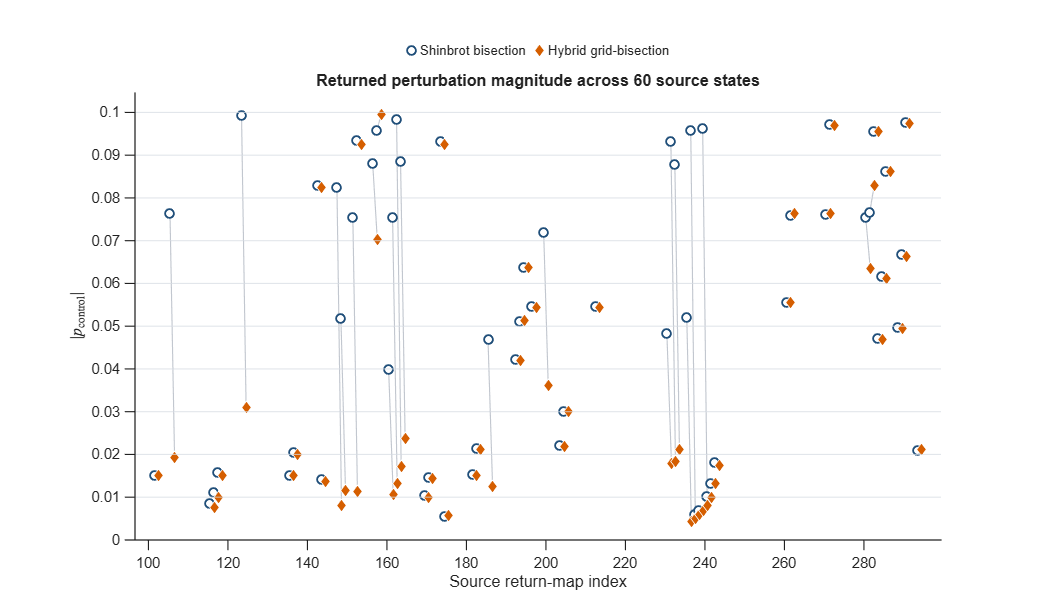


plot_shinbrot_source_ensemble(sourceEnsemble.pairedResultsTable);

walkthrough_plot_ensemble_distributions(sourceEnsemble);

## Noise-Robustness Investigation

The final investigation uses fixed-step RK4 because adaptive internal steps would make per-step coordinate noise ambiguous. In `next_valid_section_crossing_noisy_rk4`, independent Gaussian noise is applied before the corresponding integration step:


$$X \leftarrow X+\sigma_{\mathrm{noise}}\eta,\qquad
 \eta\sim N(0,I_3).$$


Section crossings are detected manually by linear interpolation across the integrated RK4 segment. Crossings caused solely by the instantaneous noise jump are deliberately excluded. The final noise study uses the verified bisection method only. The retained mode is `sectionRetargetMode`: after each accepted section crossing that misses the target, the verified bisection search is rerun from that accepted section state. This differs from a one-time targeting experiment and is also not a full reproduction of every recovery mechanism discussed by Shinbrot et al.

noise.dt = 0.001;
noise.maxTimeToNextValidSection = 80;
noise.maxControlledCrossings = 60;
noise.maxRejectedCrossings = 250;
noise.maxStateNorm = 1e5;
noise.maxRk4Steps = 12000;
noise.axisDefinition = ...
    'per-step per-coordinate Gaussian standard deviation';
noise.directlyComparableToPaperFigure6 = false;

noiseControl = control;
noiseControl.searchMethod = verifiedBisectionIdentifier;

noiseSweep = walkthrough_noise_sweep_settings( ...
    verifiedBisectionIdentifier, sourceIndex, runNoiseSmokeOnly);

if runExpensiveNoiseSweep
    noiseResults = main_shinbrot_noise_demo(true, runNoiseSmokeOnly);
else
    currentNoiseConfig = build_bisection_noise_config( ...
        sourceState, target, params, noiseControl, noise, noiseSweep);
    [noiseResults, savedNoiseLoaded, noiseDifferences] = ...
        load_valid_bisection_noise_results( ...
        noiseSweep.outputMatFile, currentNoiseConfig);
    if ~savedNoiseLoaded
        error(['No valid completed bisection-noise result was loaded. ', ...
            'Set runExpensiveNoiseSweep = true to regenerate. ', ...
            'Validation differences: %s'], ...
            strjoin(cellstr(noiseDifferences), '; '));
    end
end

Error using main_shinbrot_noise_demo
Too many input arguments.


noiseCompletion = table(string(noiseResults.searchMethod), ...
    noiseResults.completed, noiseResults.isSmokeTest, ...
    noiseResults.totalTrials, numel(noiseResults.sigmaNoiseValues), ...
    noiseResults.numTrials, string(noiseResults.modes{1}), ...
    string(noiseResults.noiseAxisDefinition), ...
    noiseResults.directlyComparableToPaperFigure6, ...
    'VariableNames', {'SearchMethod', 'Completed', 'IsSmokeTest', ...
    'TotalTrials', 'NumberNoiseLevels', 'TrialsPerLevel', ...
    'RetargetingMode', 'NoiseAxisDefinition', ...
    'DirectlyComparableToPaperFigure6'});
disp(noiseCompletion);
disp(noiseResults.summaryTable);

failureRows = noiseResults.trialsTable(~noiseResults.trialsTable.Hit, :);
failureSummary = table(height(failureRows), ...
    sum(noiseResults.trialsTable.IntegrationFailed), ...
    'VariableNames', {'NumberFailedTargetingTrials', ...
    'NumberIntegrationFailures'});
disp(failureSummary);
plot_noise_results(noiseResults, target, params, noise);
walkthrough_plot_noise_summary(noiseResults);

## Scaling in the Control Bound

The fourth component tests the scaling relation n_t ~ ln(1/dp)/lambda, which is the only quantitative theoretical prediction of the original paper. The maximum admissible perturbation is varied over the decades from 1e-2 to 1, twenty-five randomly chosen source states are directed to the target at each value, and the mean number of accepted crossings is regressed on log10(dp). The fitted slope is converted to an exponent through lambda = ln(10)/|s| and compared both with the published fit and with the exponent measured directly from the nominal return map. The horizon cap is raised for this component, because a cap that binds at small dp would truncate the trend being measured, and every trial that terminates at the cap is counted so that a binding cap is visible. The sweep is expensive, so a saved result is loaded unless runControlBoundSweep is set.

controlBoundSweepFile = 'shinbrot_control_bound_sweep.mat';

if runControlBoundSweep
    controlBoundResults = shinbrot_control_bound_sweep(mapData, ...
        struct('saveMatFile', controlBoundSweepFile));
elseif isfile(controlBoundSweepFile)
    loadedControlBound = load(controlBoundSweepFile, 'results');
    controlBoundResults = loadedControlBound.results;
    fprintf('Loaded saved control-bound sweep from %s.\n', controlBoundSweepFile);
else
    error(['No saved control-bound sweep was found. ', ...
        'Set runControlBoundSweep = true to generate it.']);
end

disp(controlBoundResults.levels);

controlBoundSummary = table( ...
    controlBoundResults.fit.slope, ...
    controlBoundResults.fit.slopeStandardError, ...
    controlBoundResults.fit.rSquared, ...
    controlBoundResults.fit.lambdaFromSlope, ...
    controlBoundResults.published.slope, ...
    controlBoundResults.returnMapLambda, ...
    controlBoundResults.returnMapImpliedSlope, ...
    controlBoundResults.crossingRatio.ratio, ...
    controlBoundResults.lambdaPerPlaneCrossing, ...
    string(controlBoundResults.classification), ...
    controlBoundResults.capBound, ...
    'VariableNames', {'FittedSlope', 'SlopeStandardError', 'RSquared', ...
    'LambdaFromSlope', 'PublishedSlope', 'ReturnMapLambda', ...
    'ReturnMapImpliedSlope', 'PlaneToAcceptedRatio', ...
    'LambdaPerPlaneCrossing', 'Classification', 'HorizonCapBound'});
disp(controlBoundSummary);

## Interpretation and Limitations

The principal deterministic example verifies that both retained searches can target the selected fixed-point neighbourhood from the same source in three accepted crossings. In this example the revised Shinbrot bisection method finds the slightly smaller perturbation, while the hybrid method finds the smaller final residual. This single example does not establish universal superiority. The ensemble benchmark is the appropriate place to compare distributions of horizons, magnitudes, residuals and costs.

The hybrid method depends on grid resolution and on the rule used to refine adjacent brackets. The bisection method depends on how discontinuities in crossing identity are isolated and on the maximum isolation depth. Both methods depend on the Poincare section, target tolerance, ODE tolerances, source selection and maximum search horizon.

The noise study is a fixed-step, coordinate-noise experiment with accepted-section retargeting by the verified bisection method. Its noise axis is a per-step coordinate standard deviation in Lorenz units and is not directly comparable with every axis choice in the original paper. The results should therefore be interpreted as robustness diagnostics for this implementation rather than as a complete reproduction of all noisy recovery experiments.

interpretationTable = table( ...
    ["Principal example"; "60-source ensemble"; "Noise sweep"], ...
    ["Both deterministic methods replay into the target interval"; ...
     "Both methods attain verified hits across the saved source set"; ...
     "Bisection-only accepted-section retargeting is tested under RK4 noise"], ...
    ["Single-source comparison only"; ...
     "Summary statistics do not prove one method is universally better"; ...
     "Noise axis is implementation-specific and not directly paper-equivalent"], ...
    'VariableNames', {'StudyPart', 'SupportedFinding', 'Limitation'});
disp(interpretationTable);

## Final Reproducibility Summary

The table below lists the main supporting `.m` files called by this Live Script. To rerun the principal demonstration, press Run in this Live Script or call the deterministic functions shown above. To regenerate the ensemble set `runExpensiveEnsemble = true`. To regenerate the full noise sweep set `runExpensiveNoiseSweep = true`; the default is to load the verified completed sweep.

supportingFiles = walkthrough_supporting_files_table(projectPath);
disp(supportingFiles);

finalSummary = table( ...
    target.x, target.tolerance, sourceIndex, sourceX, ...
    bisectionSearch.selectedP, hybridSearch.selectedP, ...
    bisectionSearch.horizon, hybridSearch.horizon, ...
    bisectionReplay.targetError, hybridReplay.targetError, ...
    uncontrolled.numCrossings, ...
    'VariableNames', {'TargetX', 'TargetTolerance', 'SourceIndex', ...
    'SourceX', 'BisectionP', 'HybridP', 'BisectionHorizon', ...
    'HybridHorizon', 'BisectionReplayError', 'HybridReplayError', ...
    'UncontrolledCrossingsToHit'});
disp(finalSummary);

fprintf('Shinbrot targeting walkthrough completed successfully.\n');

## Local Helper Functions

function projectPath = walkthrough_project_path()
activeFile = '';
try
    activeFile = matlab.desktop.editor.getActiveFilename;
catch
end
if ~isempty(activeFile) && isfile(activeFile)
    projectPath = fileparts(activeFile);
else
    projectPath = fileparts(mfilename('fullpath'));
    if isempty(projectPath) || ~isfolder(projectPath)
        projectPath = pwd;
    end
end
if ~isfile(fullfile(projectPath, 'lorenz_rhs.m'))
    projectPath = pwd;
end
if ~isfile(fullfile(projectPath, 'lorenz_rhs.m'))
    error('Could not locate the Shinbrot targeting project folder.');
end
end

function walkthrough_plot_lorenz_section(mapData, sourceState, target, params)
figure('Name', 'Lorenz attractor, accepted section, source and target', ...
    'Color', 'w');
plot3(mapData.X(:, 1), mapData.X(:, 2), mapData.X(:, 3), ...
    'Color', [0.08, 0.30, 0.68], 'LineWidth', 0.55);
hold on;
walkthrough_draw_section_half_plane(mapData.X, params);
scatter3(mapData.states(1, :), mapData.states(2, :), ...
    mapData.states(3, :), 10, [0.15, 0.45, 0.80], 'filled', ...
    'MarkerFaceAlpha', 0.25, 'DisplayName', 'Accepted crossings');
plot3(sourceState(1), sourceState(2), sourceState(3), 'ko', ...
    'MarkerFaceColor', 'y', 'MarkerSize', 8, 'DisplayName', 'Source');
plot3(target.state(1), target.state(2), target.state(3), 'rp', ...
    'MarkerFaceColor', 'r', 'MarkerSize', 13, 'DisplayName', 'Target');
grid on; box on; view(38, 24);
xlabel('x'); ylabel('y'); zlabel('z');
title(sprintf('Lorenz attractor and accepted section z = %.3f, x > %.1f', ...
    params.zSection, params.xSectionMin));
legend('Location', 'best');
hold off;
end

function walkthrough_draw_section_half_plane(X, params)
xLimits = [params.xSectionMin, max(X(:, 1))];
yLimits = [min(X(:, 2)), max(X(:, 2))];
[xPlane, yPlane] = meshgrid(xLimits, yLimits);
zPlane = params.zSection * ones(size(xPlane));
surf(xPlane, yPlane, zPlane, 'FaceColor', [0.95, 0.68, 0.10], ...
    'FaceAlpha', 0.22, 'EdgeColor', 'none', ...
    'DisplayName', 'Accepted half-plane');
end

function walkthrough_plot_return_map(mapData, sourceState, target)
figure('Name', 'Scalar Poincare return map', 'Color', 'w');
plot(mapData.xN, mapData.xNext, '.', 'Color', [0.18, 0.43, 0.72], ...
    'MarkerSize', 6, 'DisplayName', 'Return-map samples');
hold on;
mapLimits = [min([mapData.xN, mapData.xNext]), ...
    max([mapData.xN, mapData.xNext])];
plot(mapLimits, mapLimits, 'k--', 'LineWidth', 1, ...
    'DisplayName', 'Identity line');
plot(sourceState(1), target.x, 'ko', 'MarkerFaceColor', 'y', ...
    'MarkerSize', 8, 'DisplayName', 'Source scalar coordinate');
plot(target.x, target.x, 'rp', 'MarkerFaceColor', 'r', ...
    'MarkerSize', 13, 'DisplayName', 'Target fixed point');
grid on; box on; axis equal;
xlim(mapLimits); ylim(mapLimits);
xlabel('X_n');
ylabel('X_{n+1}');
title('Nominal scalar return map, pControl = 0');
legend('Location', 'best');
hold off;
end

function replay = walkthrough_replay_parameter(sourceState, target, params, search)
replay.hit = false;
replay.numCrossings = Inf;
replay.physicalTime = Inf;
replay.targetError = Inf;
replay.failed = false;
replay.t = [];
replay.X = [];
replay.states = [];
replay.xSequence = sourceState(1);
replay.replayTime = NaN;
if ~search.found || ~isfinite(search.selectedP) || ~isfinite(search.horizon)
    replay.failed = true;
    return;
end
currentState = sourceState(:);
currentTime = 0;
tFull = [];
XFull = [];
states = NaN(3, search.horizon);
for crossing = 1:search.horizon
    segment = next_valid_section_crossing( ...
        currentState, params, search.selectedP);
    if ~segment.success
        replay.failed = true;
        replay.numCrossings = crossing - 1;
        return;
    end
    [tFull, XFull] = walkthrough_append_segment( ...
        tFull, XFull, currentTime, segment);
    currentTime = currentTime + segment.eventTime;
    currentState = segment.eventState;
    states(:, crossing) = currentState;
end
replay.numCrossings = search.horizon;
replay.physicalTime = currentTime;
replay.targetError = abs(currentState(1) - target.x);
replay.hit = replay.targetError <= target.tolerance;
replay.t = tFull;
replay.X = XFull;
replay.states = states;
replay.xSequence = [sourceState(1), states(1, :)];
end

function [tFull, XFull] = walkthrough_append_segment(tFull, XFull, currentTime, segment)
tSegment = currentTime + segment.t;
if isempty(tFull)
    tFull = tSegment;
    XFull = segment.X;
else
    tFull = [tFull; tSegment(2:end)];
    XFull = [XFull; segment.X(2:end, :)];
end
end

function walkthrough_assert_valid_result(search, replay, target, control, label)
%WALKTHROUGH_ASSERT_VALID_RESULT Assert the properties of a valid result.
%
%   A returned perturbation is acceptable when the search reports success,
%   the horizon is finite and within the declared cap, the perturbation lies
%   inside the admissible interval, the independent replay from the
%   three-dimensional source state enters the target neighbourhood, and the
%   search-reported error agrees with the replayed error.
%
%   No particular value of p or of the final error is required.  Different
%   implementations of the search may return different admissible
%   perturbations at the same horizon, and that is a property of the problem
%   rather than an error.

assert(search.found, '%s: the search did not report a verified candidate.', label);
assert(isfinite(search.selectedP), '%s: selectedP is not finite.', label);
assert(abs(search.selectedP) <= control.deltaP + 1e-12, ...
    '%s: |p| = %.6g exceeds the admissible bound %.6g.', ...
    label, abs(search.selectedP), control.deltaP);
assert(isfinite(search.horizon) && search.horizon >= 1 && ...
    search.horizon <= control.maxSearchCrossings, ...
    '%s: horizon %g is outside 1..%d.', ...
    label, search.horizon, control.maxSearchCrossings);
assert(search.finalTargetError <= target.tolerance, ...
    '%s: search error %.6g exceeds the tolerance %.6g.', ...
    label, search.finalTargetError, target.tolerance);

assert(~replay.failed, '%s: the independent replay did not complete.', label);
assert(replay.hit, ...
    '%s: the independent replay did not enter the target interval (error %.6g).', ...
    label, replay.targetError);
assert(replay.numCrossings == search.horizon, ...
    '%s: the replay used %g crossings against a reported horizon of %g.', ...
    label, replay.numCrossings, search.horizon);

agreement = abs(search.finalTargetError - replay.targetError);
assert(agreement <= 0.01 * target.tolerance, ...
    '%s: search and replay errors differ by %.6g, more than 1%% of the tolerance.', ...
    label, agreement);

fprintf('%s: verified. p = %.10g, n = %d, replay error = %.6g, search-replay divergence = %.3g\n', ...
    label, search.selectedP, search.horizon, replay.targetError, agreement);

if agreement == 0
    fprintf(['  Note: the divergence is exactly zero, so the replay repeated the search''s\n', ...
        '  own propagation rather than recomputing it independently. The search and the\n', ...
        '  replay reach the section through the same function, so agreement is guaranteed\n', ...
        '  and is not evidence that the returned perturbation is correct. The perturbation\n', ...
        '  is not thereby wrong; this particular check simply carries no weight for it.\n']);
end
end

function tbl = walkthrough_bisection_diagnostics(search, replay)
tbl = table(string(search.method), search.found, replay.hit, ...
    search.selectedP, abs(search.selectedP), search.horizon, ...
    search.finalTargetError, replay.targetError, search.searchTime, ...
    replay.replayTime, search.parameterEvaluations, ...
    search.crossingPropagations, search.totalBisectionIterations, ...
    search.crossingSignatureEvaluations, search.discontinuitiesDetected, ...
    search.discontinuityReductions, search.continuousIntervalsExamined, ...
    search.continuousTargetBracketFound, search.bracketLow, ...
    search.bracketHigh, string(search.selectionMethod), ...
    'VariableNames', {'Method', 'SearchFound', 'ReplayHit', ...
    'SelectedP', 'AbsP', 'Horizon', 'SearchTargetError', ...
    'ReplayTargetError', 'SearchTime', 'ReplayTime', ...
    'ParameterEvaluations', 'CrossingPropagations', ...
    'TotalBisectionIterations', 'CrossingSignatureEvaluations', ...
    'DiscontinuitiesDetected', 'DiscontinuityReductions', ...
    'ContinuousIntervalsExamined', 'ContinuousTargetBracketFound', ...
    'BracketLow', 'BracketHigh', 'SelectionMethod'});
end

function tbl = walkthrough_hybrid_diagnostics(search, replay)
tbl = table(string(search.method), search.found, replay.hit, ...
    search.selectedP, abs(search.selectedP), search.horizon, ...
    search.finalTargetError, replay.targetError, search.searchTime, ...
    replay.replayTime, search.parameterEvaluations, ...
    search.crossingPropagations, search.gridEvaluations, ...
    search.finalBracketBisectionIterations, ...
    search.totalBisectionIterations, search.bracketLow, ...
    search.bracketHigh, string(search.selectionMethod), ...
    'VariableNames', {'Method', 'SearchFound', 'ReplayHit', ...
    'SelectedP', 'AbsP', 'Horizon', 'SearchTargetError', ...
    'ReplayTargetError', 'SearchTime', 'ReplayTime', ...
    'ParameterEvaluations', 'CrossingPropagations', ...
    'GridEvaluations', 'FinalBracketBisectionIterations', ...
    'TotalBisectionIterations', 'BracketLow', 'BracketHigh', ...
    'SelectionMethod'});
end

function tbl = walkthrough_hybrid_feature_table(search, target)
horizons = (1:numel(search.directGridHitsByHorizon)).';
DirectGridHits = search.directGridHitsByHorizon(:);
AdjacentBrackets = search.adjacentBracketsByHorizon(:);
VerifiedCandidates = search.verifiedCandidatesByHorizon(:);
MinimumGridDistance = min(search.distanceByHorizon, [], 2, 'omitnan');
tbl = table(horizons, DirectGridHits, AdjacentBrackets, ...
    VerifiedCandidates, MinimumGridDistance, ...
    'VariableNames', {'Horizon', 'DirectGridHits', ...
    'AdjacentBrackets', 'VerifiedCandidates', 'MinimumGridDistance'});
tbl.TargetTolerance = target.tolerance * ones(height(tbl), 1);
end

function tbl = walkthrough_principal_comparison_table(bis, bisReplay, hyb, hybReplay)
Method = ["Shinbrot bisection"; "Grid-first hybrid"];
Success = [bis.found; hyb.found];
ReplayHit = [bisReplay.hit; hybReplay.hit];
SelectedControl = [bis.selectedP; hyb.selectedP];
AbsControl = abs(SelectedControl);
Horizon = [bis.horizon; hyb.horizon];
FinalTargetError = [bis.finalTargetError; hyb.finalTargetError];
ReplayTargetError = [bisReplay.targetError; hybReplay.targetError];
SearchTime = [bis.searchTime; hyb.searchTime];
ReplayTime = [bisReplay.replayTime; hybReplay.replayTime];
TotalComputationalTime = SearchTime + ReplayTime;
SelectionMethod = [string(bis.selectionMethod); string(hyb.selectionMethod)];
tbl = table(Method, Success, ReplayHit, SelectedControl, AbsControl, ...
    Horizon, FinalTargetError, ReplayTargetError, SearchTime, ...
    ReplayTime, TotalComputationalTime, SelectionMethod);
end

function walkthrough_plot_section_sequences(uncontrolled, bisReplay, hybReplay, target)
figure('Name', 'Controlled and uncontrolled section sequences', 'Color', 'w');
tiledlayout(1, 3, 'Padding', 'compact', 'TileSpacing', 'compact');
walkthrough_plot_one_sequence(uncontrolled.xSequence, target, ...
    'Uncontrolled recurrence', [0.08, 0.35, 0.75]);
walkthrough_plot_one_sequence(bisReplay.xSequence, target, ...
    'Shinbrot bisection replay', [0.12, 0.31, 0.47]);
walkthrough_plot_one_sequence(hybReplay.xSequence, target, ...
    'Grid-first hybrid replay', [0.84, 0.37, 0.00]);
end

function walkthrough_plot_one_sequence(xSequence, target, titleText, color)
nexttile;
n = 0:(numel(xSequence) - 1);
plot(n, xSequence, '-o', 'Color', color, 'MarkerFaceColor', color, ...
    'MarkerSize', 4, 'LineWidth', 1.1);
hold on;
xPatch = [0, max(n(end), 1), max(n(end), 1), 0];
yPatch = target.x + target.tolerance * [-1, -1, 1, 1];
patch(xPatch, yPatch, [0.88, 0.12, 0.12], 'FaceAlpha', 0.10, ...
    'EdgeColor', [0.88, 0.12, 0.12], 'LineWidth', 1);
yline(target.x, 'r:', 'X_t', 'LineWidth', 1);
grid on; box on;
xlabel('Accepted section-crossing number');
ylabel('X_n');
title(titleText);
hold off;
end

function walkthrough_plot_controlled_phase_space(mapData, uncontrolled, ...
    bisReplay, hybReplay, sourceState, target, params)
figure('Name', 'Phase-space controlled and uncontrolled replays', ...
    'Color', 'w');
plot3(mapData.X(:, 1), mapData.X(:, 2), mapData.X(:, 3), ...
    'Color', [0.82, 0.82, 0.82], 'LineWidth', 0.35, ...
    'DisplayName', 'Nominal attractor');
hold on;
if ~isempty(uncontrolled.X)
    plot3(uncontrolled.X(:, 1), uncontrolled.X(:, 2), ...
        uncontrolled.X(:, 3), 'Color', [0.08, 0.35, 0.75], ...
        'LineWidth', 0.8, 'DisplayName', 'Uncontrolled');
end
if ~isempty(bisReplay.X)
    plot3(bisReplay.X(:, 1), bisReplay.X(:, 2), bisReplay.X(:, 3), ...
        'Color', [0.12, 0.31, 0.47], 'LineWidth', 1.4, ...
        'DisplayName', 'Shinbrot bisection');
end
if ~isempty(hybReplay.X)
    plot3(hybReplay.X(:, 1), hybReplay.X(:, 2), hybReplay.X(:, 3), ...
        'Color', [0.84, 0.37, 0.00], 'LineWidth', 1.4, ...
        'DisplayName', 'Grid-first hybrid');
end
walkthrough_draw_section_half_plane(mapData.X, params);
plot3(sourceState(1), sourceState(2), sourceState(3), 'ko', ...
    'MarkerFaceColor', 'y', 'MarkerSize', 8, 'DisplayName', 'Source');
plot3(target.state(1), target.state(2), target.state(3), 'rp', ...
    'MarkerFaceColor', 'r', 'MarkerSize', 13, 'DisplayName', 'Target');
grid on; box on; view(38, 24);
xlabel('x'); ylabel('y'); zlabel('z');
title('Independent controlled replays from the same source');
legend('Location', 'best');
hold off;
end

function walkthrough_plot_search_behaviour(bis, hyb, target, control)
figure('Name', 'Deterministic search behaviour', 'Color', 'w');
tiledlayout(1, 2, 'Padding', 'compact', 'TileSpacing', 'compact');

nexttile;
bar(categorical({'Discontinuities','Reductions','Continuous intervals', ...
    'Signature evaluations'}), ...
    [bis.discontinuitiesDetected, bis.discontinuityReductions, ...
    bis.continuousIntervalsExamined, bis.crossingSignatureEvaluations]);
hold on;
if isfinite(bis.bracketLow)
    subtitle(sprintf('Selected p = %.8g, bracket [%.8g, %.8g]', ...
        bis.selectedP, bis.bracketLow, bis.bracketHigh));
end
ylabel('count');
title('Shinbrot bisection diagnostics');
grid on; box on;

nexttile;
hasGridCurve = any(isfinite(hyb.gridDistance));
if hasGridCurve
    semilogy(hyb.pGrid, max(hyb.gridDistance, eps), '-o', ...
        'Color', [0.84, 0.37, 0.00], 'MarkerSize', 3, ...
        'MarkerFaceColor', [0.84, 0.37, 0.00], ...
        'DisplayName', 'Grid residual');
    hold on;
end
yline(target.tolerance, 'r--', 'Target tolerance', 'LineWidth', 1.2);
if isfinite(hyb.bracketLow)
    xline(hyb.bracketLow, ':', 'Bracket low', 'LineWidth', 1.1);
end
if isfinite(hyb.bracketHigh)
    xline(hyb.bracketHigh, ':', 'Bracket high', 'LineWidth', 1.1);
end
if hyb.found
    xline(hyb.selectedP, 'k--', 'Selected pControl', 'LineWidth', 1.2);
end
xlim([-control.deltaP, control.deltaP]);
xlabel('pControl');
ylabel('|X_n - X_t|');
title(sprintf('Hybrid grid residual, horizon n = %d', hyb.plotHorizon));
grid on; box on;
legend('Location', 'best');
end

function rhsRms = walkthrough_compute_rhs_rms(mapData, params, control, transientCrossingIndex)
transientTime = mapData.eventTimes(transientCrossingIndex);
keep = mapData.t >= transientTime;
t = mapData.t(keep);
X = mapData.X(keep, :);
duration = t(end) - t(1);
F = NaN(size(X));
for i = 1:size(X, 1)
    F(i, :) = lorenz_rhs(t(i), X(i, :).', params, 0).';
end
rhsRms.rmsFx = sqrt(trapz(t, F(:, 1).^2) / duration);
rhsRms.rmsFy = sqrt(trapz(t, F(:, 2).^2) / duration);
rhsRms.rmsFz = sqrt(trapz(t, F(:, 3).^2) / duration);
rhsRms.transientCrossingIndex = transientCrossingIndex;
rhsRms.transientTime = transientTime;
rhsRms.averagingDuration = duration;
rhsRms.maxParameterEffect = control.deltaP;
rhsRms.parameterToRmsFyRatio = control.deltaP / rhsRms.rmsFy;
rhsRms.paperApproximateRmsFy = 100;
rhsRms.rmsFyDifferenceFromPaperApproximation = ...
    rhsRms.rmsFy - rhsRms.paperApproximateRmsFy;
end

function valid = walkthrough_is_valid_source_ensemble(saved, target, control)
required = {'sourceIndices', 'methodResultsTable', ...
    'pairedResultsTable', 'summary', 'methodSummary', ...
    'studySettings', 'target', 'control'};
valid = all(isfield(saved, required));
if ~valid
    return;
end
methods = saved.methodResultsTable.Method;
methodVariables = saved.methodResultsTable.Properties.VariableNames;
pairedVariables = saved.pairedResultsTable.Properties.VariableNames;
valid = istable(saved.methodResultsTable) && ...
    istable(saved.pairedResultsTable) && istable(saved.summary) && ...
    istable(saved.methodSummary) && ...
    numel(saved.sourceIndices) == 60 && ...
    numel(unique(saved.sourceIndices)) == 60 && ...
    all(saved.sourceIndices >= 100 & saved.sourceIndices <= 300) && ...
    height(saved.methodResultsTable) == 120 && ...
    height(saved.pairedResultsTable) == 60 && ...
    sum(strcmp(methods, verified_bisection_identifier())) == 60 && ...
    sum(strcmp(methods, 'hybridGridBisection')) == 60 && ...
    all(saved.methodResultsTable.GridEvaluations(strcmp(methods, ...
        verified_bisection_identifier())) == 0) && ...
    all(ismember({'FailureCode', 'FailureReason'}, methodVariables)) && ...
    all(ismember({'ShinbrotFinalTargetError', ...
        'HybridFinalTargetError', 'ShinbrotReplayTargetError', ...
        'HybridReplayTargetError'}, pairedVariables)) && ...
    saved.studySettings.numSources == 60 && ...
    saved.studySettings.sourceSeparation == 1.5 && ...
    isequal(saved.studySettings.candidateIndices(:).', 100:300) && ...
    saved.control.maxSearchCrossings == control.maxSearchCrossings && ...
    saved.control.deltaP == control.deltaP && ...
    saved.target.x == target.x && ...
    saved.target.tolerance == target.tolerance;
end

function walkthrough_plot_ensemble_distributions(sourceEnsemble)
paired = sourceEnsemble.pairedResultsTable;
figure('Name', 'Ensemble error and search-time distributions', 'Color', 'w');
tiledlayout(1, 2, 'Padding', 'compact', 'TileSpacing', 'compact');

nexttile;
histogram(paired.ShinbrotReplayTargetError(paired.ShinbrotReplayHit), ...
    'FaceColor', [0.12, 0.31, 0.47], 'FaceAlpha', 0.65, ...
    'DisplayName', 'Shinbrot');
hold on;
histogram(paired.HybridReplayTargetError(paired.HybridReplayHit), ...
    'FaceColor', [0.84, 0.37, 0.00], 'FaceAlpha', 0.55, ...
    'DisplayName', 'Hybrid');
xlabel('Replay target error');
ylabel('source count');
title('Verified replay target errors');
legend('Location', 'best');
grid on; box on;

nexttile;
methods = sourceEnsemble.methodResultsTable.Method;
shinbrotTimes = sourceEnsemble.methodResultsTable.SearchTime( ...
    strcmp(methods, verified_bisection_identifier()));
hybridTimes = sourceEnsemble.methodResultsTable.SearchTime( ...
    strcmp(methods, 'hybridGridBisection'));
boxchart(categorical([repmat("Shinbrot", numel(shinbrotTimes), 1); ...
    repmat("Hybrid", numel(hybridTimes), 1)]), ...
    [shinbrotTimes; hybridTimes]);
ylabel('Search time');
title('Single-run ensemble search times');
grid on; box on;
end

function sweep = walkthrough_noise_sweep_settings(verifiedIdentifier, sourceIndex, isSmokeTest)
if isSmokeTest
    sweep.sigmaNoiseValues = [0, 0.05];
    sweep.numTrials = 1;
    sweep.baseSeed = 191000;
    sweep.outputMatFile = 'noise_smoke_bisection_section_retarget.mat';
    sweep.checkpointMatFile = ...
        'noise_smoke_bisection_section_retarget_checkpoint.mat';
    sweep.summaryCsvFile = 'noise_smoke_summary_bisection_section_retarget.csv';
    sweep.trialsCsvFile = 'noise_smoke_trials_bisection_section_retarget.csv';
    sweep.resumeFromCheckpoint = false;
else
    sweep.sigmaNoiseValues = ...
        [0, 0.01, 0.03, 0.05, 0.075, 0.1, 0.15, 0.2, 0.3, 0.5, 1.0];
    sweep.numTrials = 10;
    sweep.baseSeed = 91000;
    sweep.outputMatFile = 'noise_results_bisection_section_retarget.mat';
    sweep.checkpointMatFile = ...
        'noise_results_bisection_section_retarget_checkpoint.mat';
    sweep.summaryCsvFile = 'noise_summary_bisection_section_retarget.csv';
    sweep.trialsCsvFile = 'noise_trials_bisection_section_retarget.csv';
    sweep.resumeFromCheckpoint = true;
end
sweep.modes = {'sectionRetargetMode'};
sweep.searchMethod = verifiedIdentifier;
sweep.sourceIndex = sourceIndex;
sweep.isSmokeTest = isSmokeTest;
end

function walkthrough_plot_noise_summary(noiseResults)
summary = noiseResults.summaryTable;
figure('Name', 'Noise summary compact view', 'Color', 'w');
tiledlayout(1, 2, 'Padding', 'compact', 'TileSpacing', 'compact');

nexttile;
plot(summary.SigmaNoise, summary.SuccessFraction, 'o-', ...
    'LineWidth', 1.5, 'MarkerFaceColor', [0.12, 0.31, 0.47], ...
    'Color', [0.12, 0.31, 0.47]);
ylim([-0.05, 1.05]);
xlabel('sigma_noise');
ylabel('success fraction');
title('Noise-sweep success fraction');
grid on; box on;

nexttile;
plot(summary.SigmaNoise, summary.MeanRetargetingEvents, 's-', ...
    'LineWidth', 1.5, 'MarkerFaceColor', [0.84, 0.37, 0.00], ...
    'Color', [0.84, 0.37, 0.00]);
xlabel('sigma_noise');
ylabel('mean retargeting events');
title('Accepted-section retargeting effort');
grid on; box on;
end

function files = walkthrough_supporting_files_table(projectPath)
names = [
    "lorenz_rhs.m"
    "poincare_event.m"
    "next_valid_section_crossing.m"
    "generate_return_map.m"
    "uncontrolled_hitting_time_1d.m"
    "search_parameter_to_target.m"
    "run_shinbrot_discontinuity_aware_bisection.m"
    "evaluate_shinbrot_crossing_signature.m"
    "find_hybrid_grid_features.m"
    "select_verified_hybrid_candidate.m"
    "benchmark_shinbrot_search_methods.m"
    "benchmark_shinbrot_source_ensemble.m"
    "next_valid_section_crossing_noisy_rk4.m"
    "rk4_lorenz_step.m"
    "run_noise_sweep.m"
    "run_noisy_targeting_trial.m"
    "build_bisection_noise_config.m"
    "load_valid_bisection_noise_results.m"
    "plot_shinbrot_source_ensemble.m"
    "plot_noise_results.m"
    ];
roles = [
    "Lorenz vector field"
    "Poincare plane event"
    "Accepted deterministic section crossing"
    "Nominal scalar return-map data"
    "Uncontrolled recurrence baseline"
    "Dispatcher for both deterministic searches"
    "Verified Shinbrot bisection search"
    "Crossing-order signature diagnostic"
    "Hybrid direct-hit and bracket detection"
    "Hybrid verified-candidate tie-break"
    "Single-source repeated timing benchmark"
    "60-source deterministic ensemble benchmark"
    "Noisy fixed-step accepted crossing"
    "Fourth-order Runge-Kutta step"
    "Bisection-only noise sweep"
    "One noisy retargeting trial"
    "Noise configuration signature"
    "Validated completed noise-result loader"
    "Ensemble figures"
    "Noise figures"
    ];
exists = false(numel(names), 1);
for i = 1:numel(names)
    exists(i) = isfile(fullfile(projectPath, names(i)));
end
files = table(names, roles, exists, ...
    'VariableNames', {'FileName', 'Role', 'Exists'});
end